clear

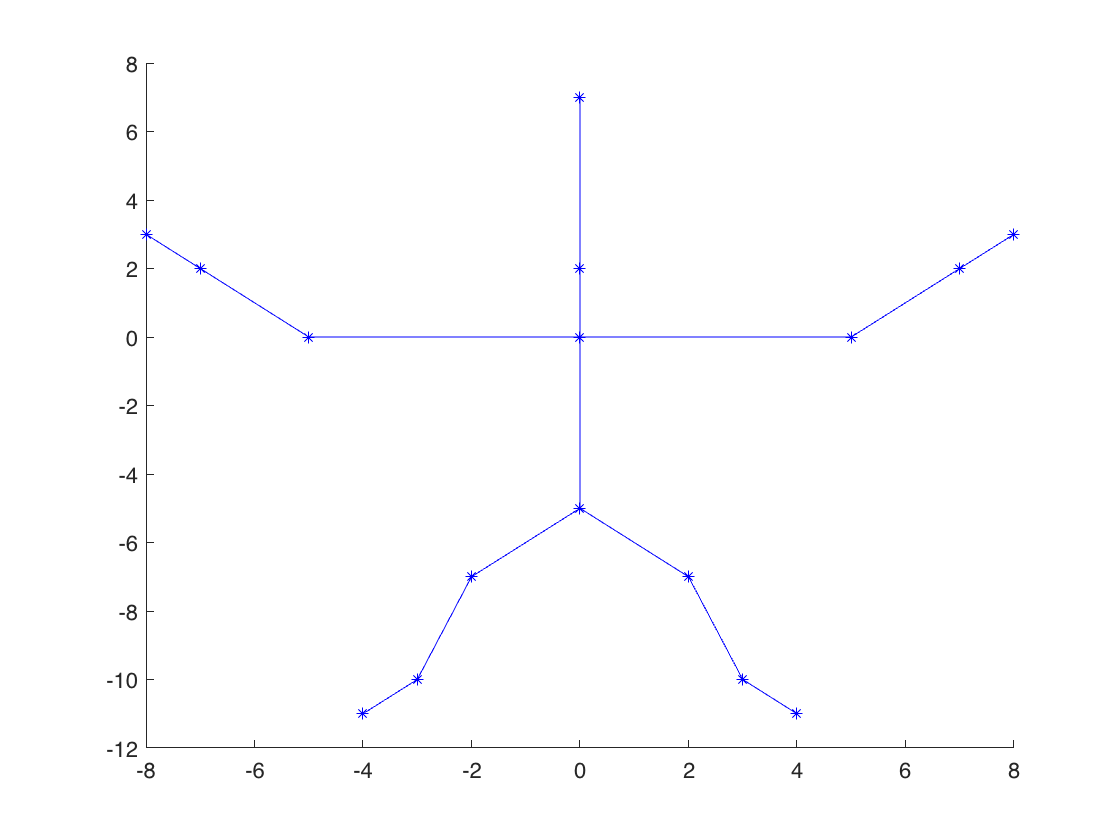

% Section1: build skeleton
head = [0, 0; 2, 7];
neck = [0, 0; 0, 2];
left_upper_arm = [0, -5; 0, 0];
left_forearm = [-5, -7; 0, 2];
left_hand = [-7, -8; 2, 3];
right_upper_arm = [0, 5; 0, 0];
right_forearm = [5, 7; 0, 2];
right_hand = [7, 8; 2, 3];
body = [0, 0; 0, -5];
left_thigh = [0, -2; -5, -7];
left_lower_leg = [-2, -3; -7, -10];
left_feet = [-3, -4; -10, -11];
right_thigh = [0, 2; -5, -7];
right_lower_leg = [2, 3; -7, -10];
right_feet = [3, 4; -10, -11];
skeleton = {head, neck, left_upper_arm, left_forearm, left_hand, right_upper_arm, right_forearm, right_hand, body, left_thigh, left_lower_leg, left_feet, right_thigh, right_lower_leg, right_feet};

% plot
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

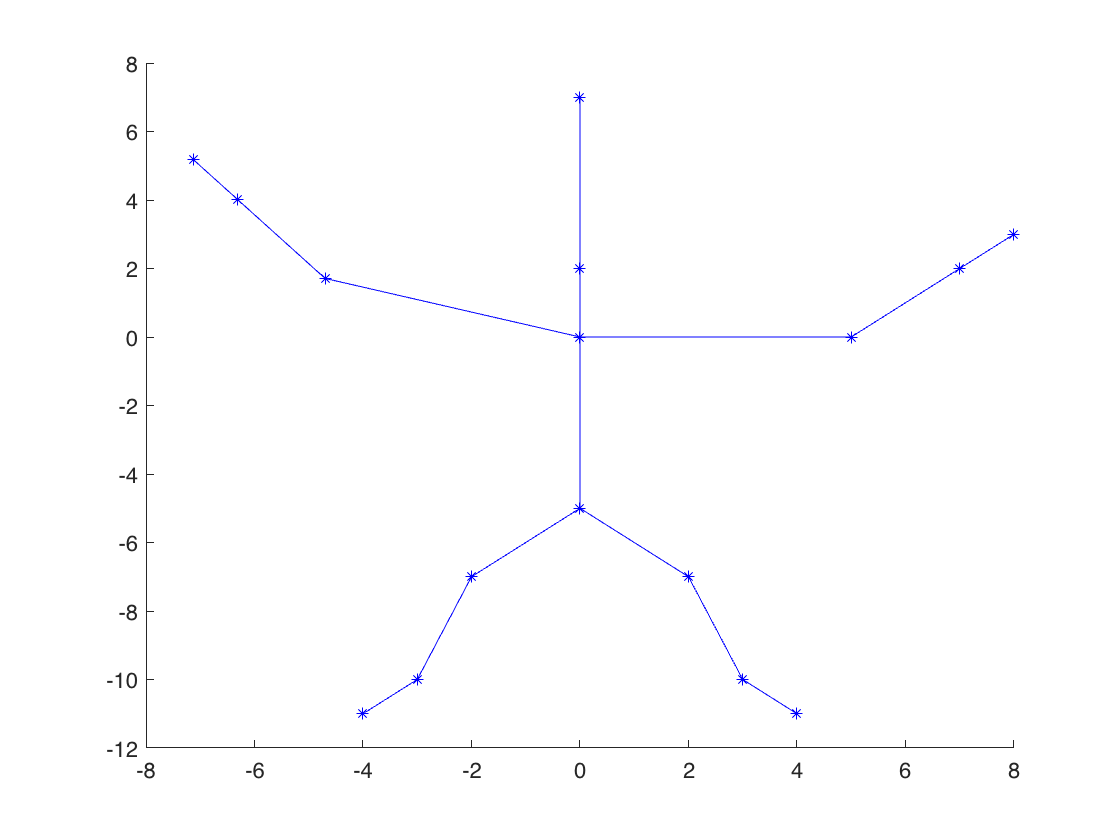

% Section2: rotate left_upper_arm, left_forearm and left_hand
% Enter your code here

% move and rotate left_upper_arm
theta =20;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
tmp = trans*cell2mat(skeleton(3));
dxy = tmp - cell2mat(skeleton(3));
skeleton(3) = mat2cell(tmp,2,2);

%move left_forearm and left_hand accordingly
dxy = dxy(:,2);
skeleton(4) = mat2cell(cell2mat(skeleton(4)) + dxy,2,2);
skeleton(5) = mat2cell(cell2mat(skeleton(5)) + dxy,2,2);

% move and rotate left_forearm
theta =10;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(4));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(4) = mat2cell(new_coor,2,2);

%move left_hand accordingly
tmp = cell2mat(skeleton(4));
dxy = tmp - coor;
dxy = dxy(:,2);
skeleton(5) = mat2cell(cell2mat(skeleton(5)) + dxy,2,2);

% move and rotate left_hand
theta =10;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(5));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(5) = mat2cell(new_coor,2,2);

% Plot the result
% Enter your code here
clf
figure(2)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

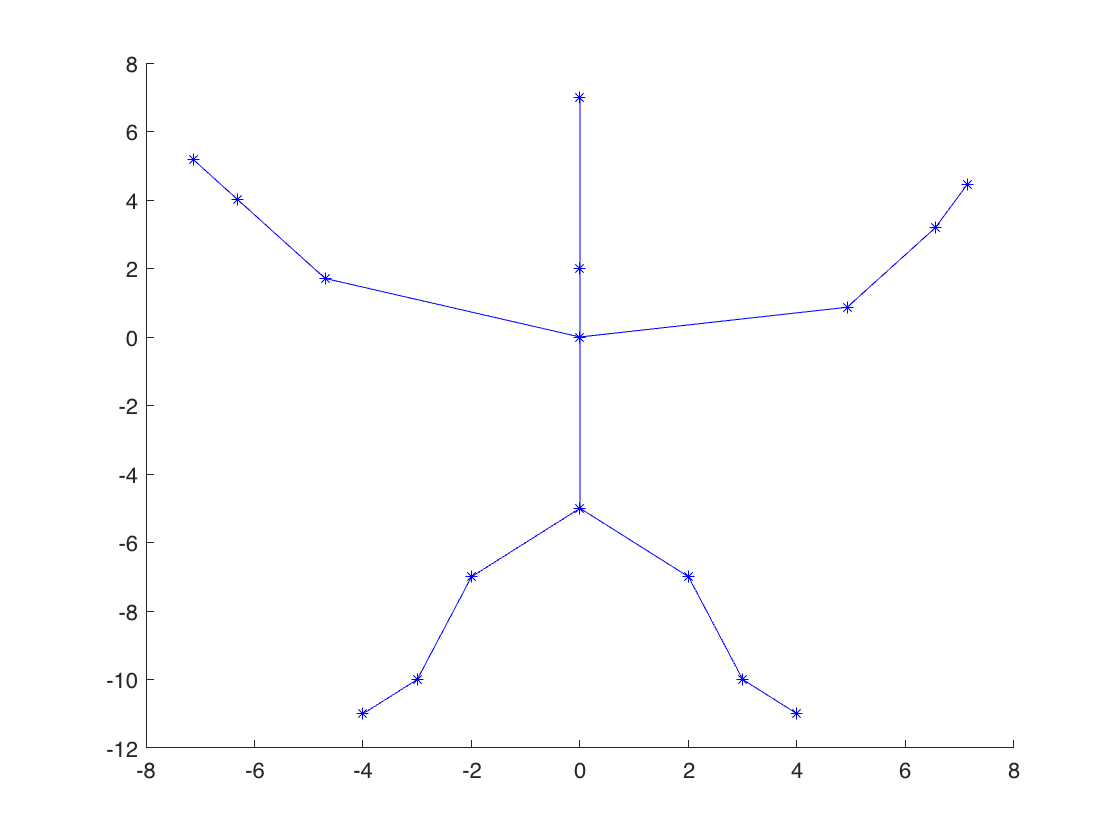

% Section3: rotate right_upper_arm, right_forearm and right_hand
% Enter your code here

% move and rotate right_upper_arm
theta =-10;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
tmp = trans*cell2mat(skeleton(6));
dxy = tmp - cell2mat(skeleton(6));
skeleton(6) = mat2cell(tmp,2,2);

%move right_forearm and right_hand accordingly
dxy = dxy(:,2);
skeleton(7) = mat2cell(cell2mat(skeleton(7)) + dxy,2,2);
skeleton(8) = mat2cell(cell2mat(skeleton(8)) + dxy,2,2);

% move and rotate right_forearm
theta =-10;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(7));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(7) = mat2cell(new_coor,2,2);

%move right_hand accordingly
tmp = cell2mat(skeleton(7));
dxy = tmp - coor;
dxy = dxy(:,2);
skeleton(8) = mat2cell(cell2mat(skeleton(8)) + dxy,2,2);

% move and rotate right_hand
theta =-20;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(8));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(8) = mat2cell(new_coor,2,2);

% Plot the result
% Enter your code here
clf
figure(3)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

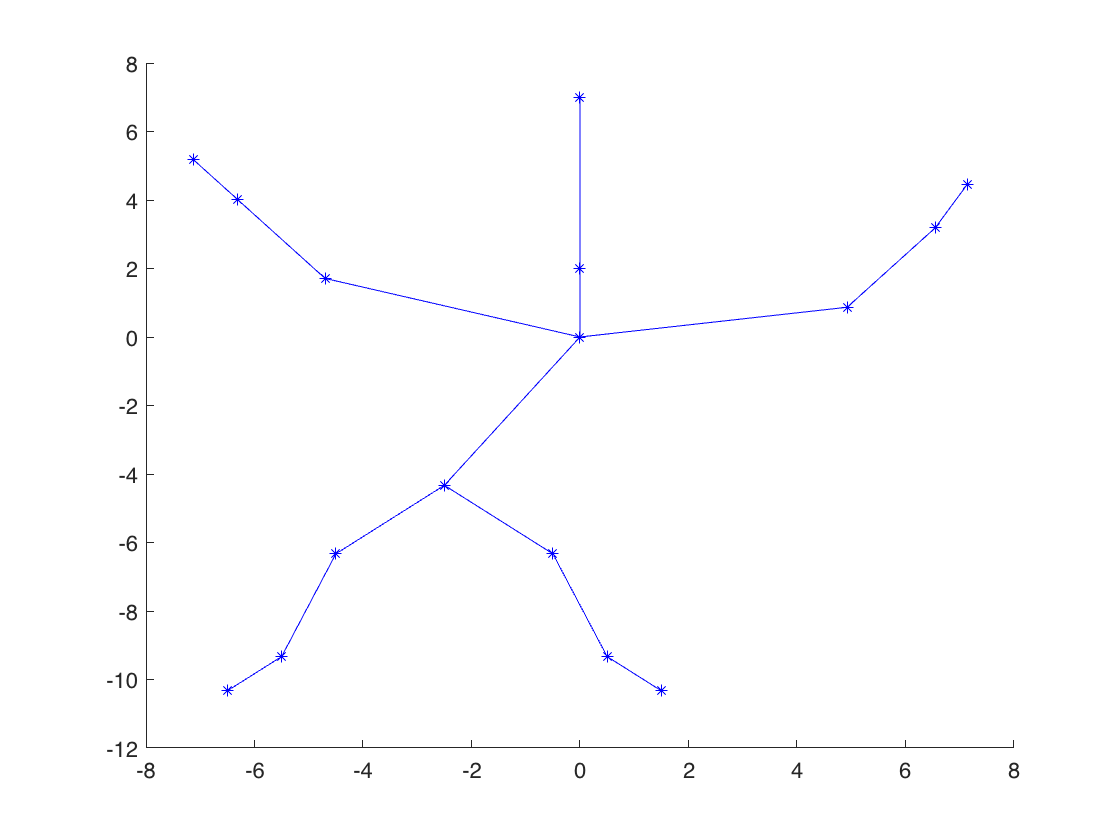

% Section4: rotate the body and update the related body part
% Enter your code here

% move and rotate body
theta =30;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
tmp = trans*cell2mat(skeleton(9));
dxy = tmp - cell2mat(skeleton(9));
skeleton(9) = mat2cell(tmp,2,2);

%move left_thigh, left_lower_leg, left_feet, right_thigh, right_lower_leg, right_feet accordingly
dxy = dxy(:,2);
skeleton(10) = mat2cell(cell2mat(skeleton(10)) + dxy,2,2);
skeleton(11) = mat2cell(cell2mat(skeleton(11)) + dxy,2,2);
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + dxy,2,2);
skeleton(13) = mat2cell(cell2mat(skeleton(13)) + dxy,2,2);
skeleton(14) = mat2cell(cell2mat(skeleton(14)) + dxy,2,2);
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + dxy,2,2);

% Plot the result
% Enter your code here
clf
figure(4)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

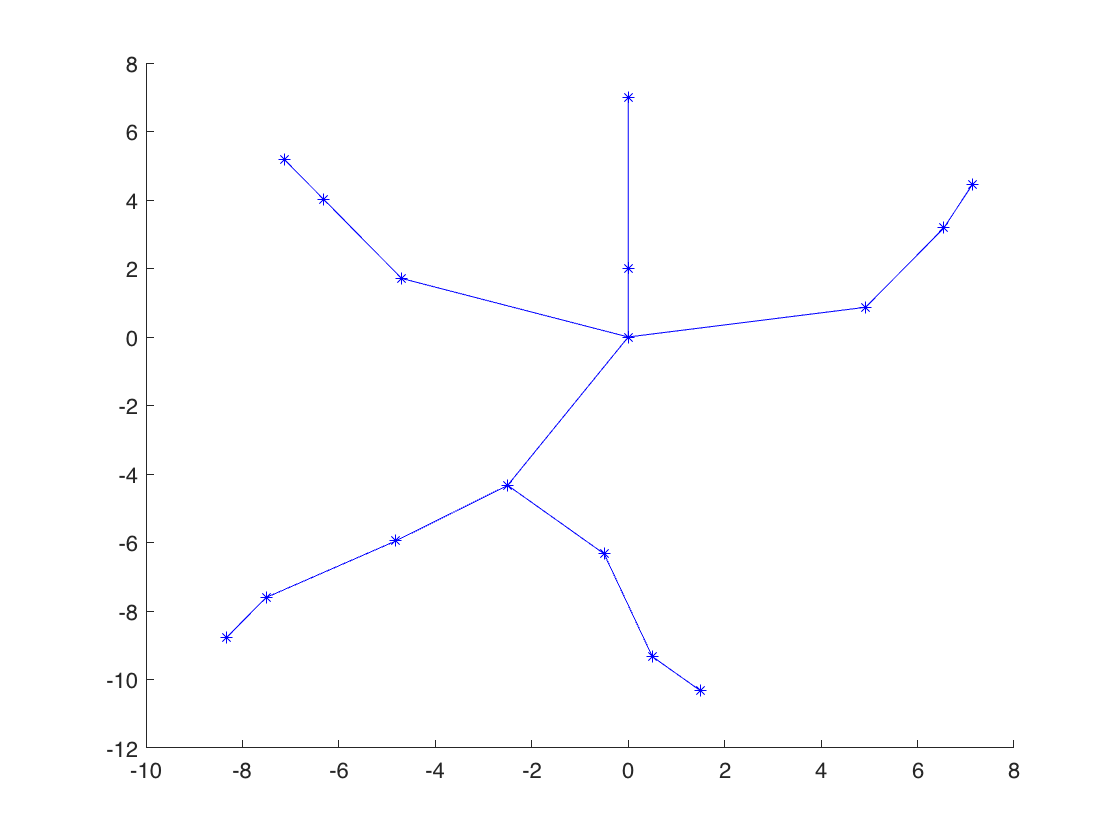

% Section5: rotate left_thigh, left_lower_leg and left_feet
% Enter your code here

% move and rotate left_thigh
theta =10;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(10));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(10) = mat2cell(new_coor,2,2);

%move left_lower_leg and left_feet accordingly
tmp = cell2mat(skeleton(10));
dxy = tmp - coor;
dxy = dxy(:,2);
skeleton(11) = mat2cell(cell2mat(skeleton(11)) + dxy,2,2);
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + dxy,2,2);

% move and rotate left_lower_leg
theta =40;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(11));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(11) = mat2cell(new_coor,2,2);

%move left_feet accordingly
tmp = cell2mat(skeleton(11));
dxy = tmp - coor;
dxy = dxy(:,2);
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + dxy,2,2);

% move and rotate left_feet
theta =-10;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(12));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(12) = mat2cell(new_coor,2,2);

% Plot the result
% Enter your code here
clf
figure(5)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

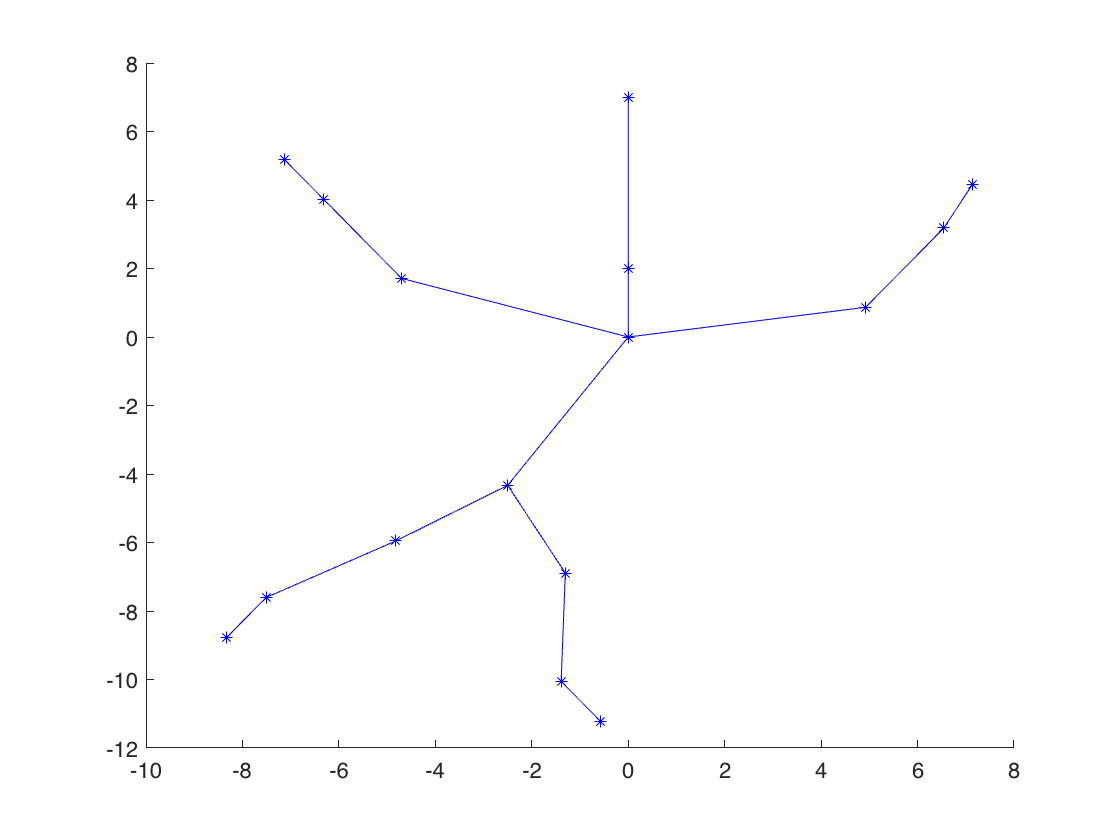

% Section6: rotate right_thigh, right_lower_leg and right_feet
% Enter your code here

% move and rotate right_thigh
theta =20;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(13));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(13) = mat2cell(new_coor,2,2);

%move right_lower_leg and right_feet accordingly
tmp = cell2mat(skeleton(13));
dxy = tmp - coor;
dxy = dxy(:,2);
skeleton(14) = mat2cell(cell2mat(skeleton(14)) + dxy,2,2);
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + dxy,2,2);

% move and rotate right_lower_leg
theta =20;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(14));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(14) = mat2cell(new_coor,2,2);

%move right_feet accordingly
tmp = cell2mat(skeleton(14));
dxy = tmp - coor;
dxy = dxy(:,2);
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + dxy,2,2);

% move and rotate right_feet
theta =10;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(15));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(15) = mat2cell(new_coor,2,2);

% Plot the result
% Enter your code here
clf
figure(6)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

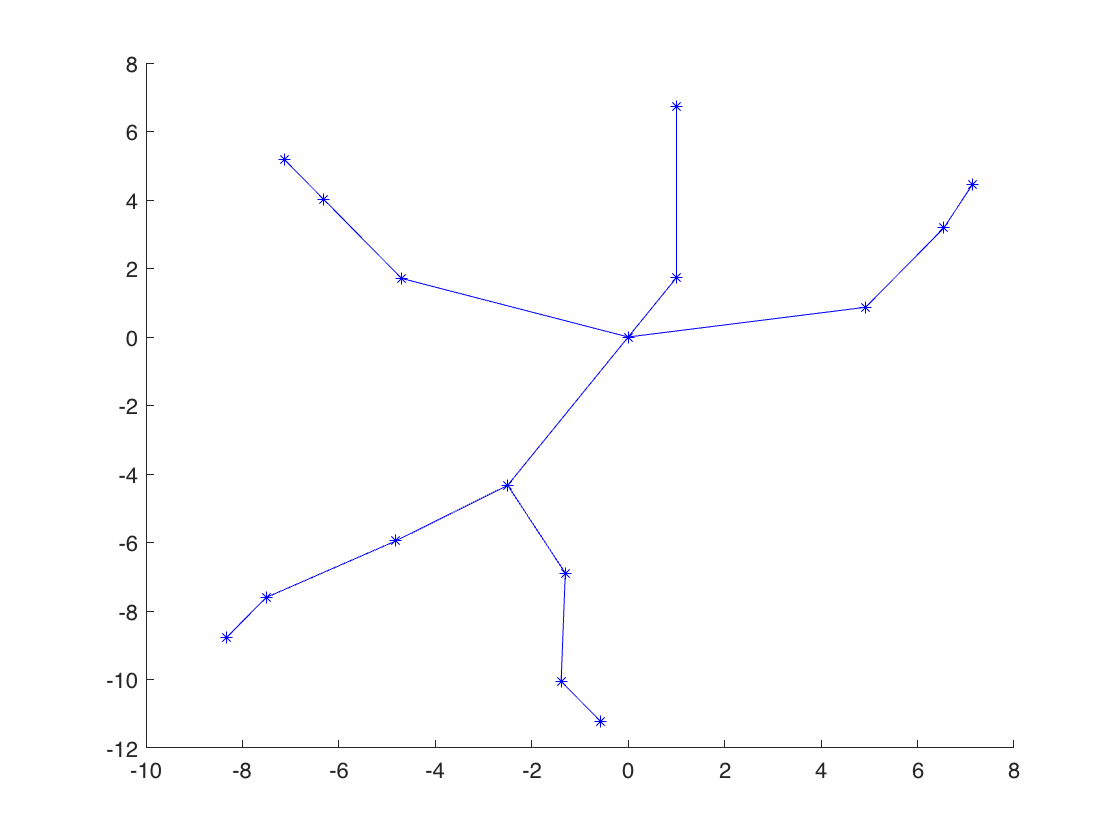

% Section7: rotate head and neck
% Enter your code here

% move and rotate neck
theta =30;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
tmp = trans*cell2mat(skeleton(2));
dxy = tmp - cell2mat(skeleton(2));
skeleton(2) = mat2cell(tmp,2,2);

%move head accordingly
dxy = dxy(:,2);
skeleton(1) = mat2cell(cell2mat(skeleton(1)) + dxy,2,2);

% move and rotate head
theta =0;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(1));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(1) = mat2cell(new_coor,2,2);

% Plot the result
% Enter your code here
clf
figure(7)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end